# M1 AHU Vibration Analysis

This script uses the AHU vibration power spectrum density (PSD) $U_\text{seg}(j\omega)$ and the telescope frequency response $H(j\omega)$ to perform a set of analysis regarding the impact of the vibration load into the image quality.

Preamble

- Clear workspace

- Radians to mas ($10^{-3}$ arc seconds) conversion constant

- Define root sum of squares (RSS) function

clearvars
rad2mas = (180/pi * 3600 * 1000);   % Radians to mili arc second conversion constant
rss = @(x,dir)sqrt(sum(x.^2,dir));  % Root of the sum of squared values function

## Load AHU vibration PSD

load("ahu_psd_1KHz_1400rpm.mat","psdAHUf","freq");

`psdAHUf` provides the vibration power spectrum density (PSD) data $U_\text{seg}(j\omega)$ as an $n_f \times 6$ matrix, where $n_f$ is the number of frequency samples. The frequencies in (Hz) are available from `freq.` The columns are the forces ($F_x$, $F_y$, and $F_z$) and moments ($M_x$, $M_y$, and $M_z$), expressed in $\text{N}^2/\text{Hz}$ and $\text{N}^2\text{m}^2/\text{Hz}$, respectively.

## Calculate the M1 AHU transfer function

Choose the wavefront control mode corresponding to the rejection transfer function to be applied to the frequency response model outputs:

WFC_MODE = "LTAO"

WFC_MODE = "LTAO"

Checking for available FR files for model 20251110_1617...
FR data in G_20251110_1617zeta2pct_ahu_fr_var_1.mat
matches the PSD frequency points of the AHU PSD.
Adding the effect of the mount (AZ/EL/GIR) feedback control loop...

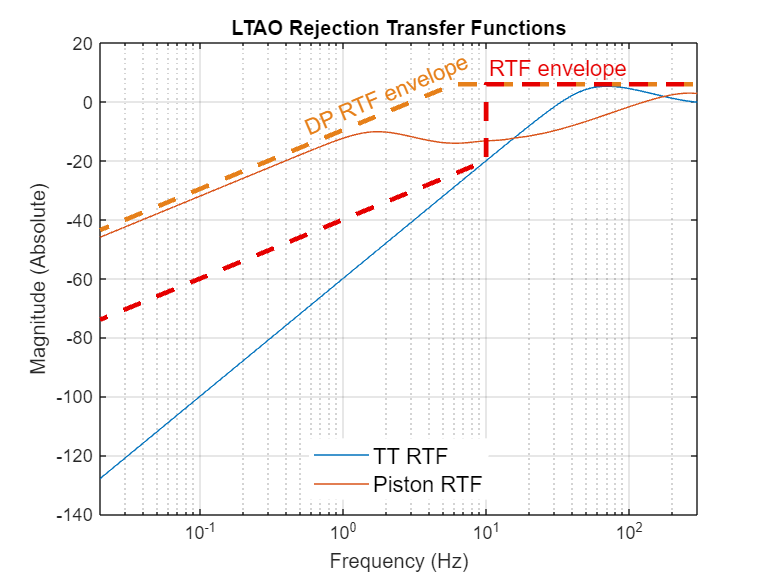

plot_wfc_rtf = false;
run('calc_m1ahu_fr.mlx');

## General analysis

Let $H_\text{ttp}(\j\omega)$the frequency response matrix represent the GMT structural dynamics whose inputs are the forces and moments applied to nodes at the M1 fan locations and the outputs are the segment tip-tilt (TT) and the piston at the exit pupil. Refer to script `calc_m1ahu_fr.mlx` for details.

In the following, we compute the TT and piston PSD ($$\text{mas}^2/\text{Hz}$$ and $$\text{nm}^2/\text{Hz}$$, respectively) using 


$$Y_\text{ttp}(j\omega) = \left|H_\text{ttp}(j\omega) \right|^2
\left(\mathbf{1}_{98} \otimes U_{\text{AHU}}(j\omega)\right)$$


The symbol $
\otimes$ stands for the Kronecker product and $\mathbf{1}_{n_1}$ is an $n_1$-dimensional column vector filled with ones, such that

$\mathbf{1}_3 \otimes U_\text{AHU}(j\omega) = \left[
\begin{array}{c}
U_\text{AHU}(j\omega) \\ U_\text{AHU}(j\omega) \\ U_\text{AHU}(j\omega)
\end{array}
\right]$.

Therefore, $\mathbf{1}_{98} \otimes U_\text{AHU}(j\omega)$ means that the same force and moment vibration load $U_\text{AHU}$ is applied in all the air handling unit nodes. The power spectrum density $Y_\text{TTP}$ is 21-dimensional. According to the telescope frequency response model, the first 14 elements of $Y_\text{TTP}$ are the tip-tilt PSD and the last 7 provide the segment piston, *i.e.*

$Y_\text{ttp}(j\omega) = \left[
\begin{array}{c}
Y_\text{tt}(j\omega) \\ Y_\text{p}(j\omega) 
\end{array}
\right]$.

y_ttp_psd = zeros(21,nw);

U_ahu = kron(ones(1,14*7), psdAHUf);
% Each iteration provides the Tip/tilt/piston PSD as a response of the
% forces (and moments) applied to the M1 AHU locations.
for k1 = 1:7
    y_ttp_psd(k1,:) = sum(abs(squeeze(rad2mas*H_ttp.ResponseData(k1,:,:)))'.^2 .* U_ahu, 2);
    y_ttp_psd(k1+7,:) = sum(abs(squeeze(rad2mas*H_ttp.ResponseData(k1+7,:,:)))'.^2 .* U_ahu, 2);
    y_ttp_psd(k1+14,:) = sum(abs(squeeze(1e9*H_ttp.ResponseData(k1+14,:,:)))'.^2 .* U_ahu, 2);
end

### Segment Tip-tilt

Let $Y_\text{tt}(j\omega)$the 14-dimensional vector of segment tip-tilt (in $$\text{mas}^2/\text{Hz}$$). In the following, we present


$$\breve{Y}_{\text{tt},i}(j\omega) = 
Y_{\text{tt},i}(j\omega) +
Y_{\text{tt},i+7}(j\omega)$$


which is the power spectrum density of the tip-tilt contribution for each for each segment $i \in \{1,2,\ldots,7\}$. $Y_{\text{tt},i}(j\omega)$ denotes the $i^\text{th}$-element of $Y_\text{tt}(j\omega)$.

### Segment Piston

Next, we present the differential piston error induced by the AHU forces (and moments) for each segment. The **differential** piston error $\breve{Y}_\text{dp}(j\omega)$ power spectral density (PSD) is obtained as the square of the differential piston amplitude spectral density (ASD), which is calculated by subtracting the average ASD over the seven segments from the segment piston ASD. So,


$$\breve{Y}_{\text{dp},i}(j\omega) = 
\left(
\sqrt{Y_{\text{p},i}(j\omega)} - \frac{1}{7} \sum_{i=1}^7
\sqrt{Y_{\text{p},i}(j\omega)} 
\right)^2,$$


where $Y_{\text{p},i}(j\omega)$ denotes the $i^\text{th}$-element of the 7-dimensional vector $Y_\text{p}(j\omega)$.

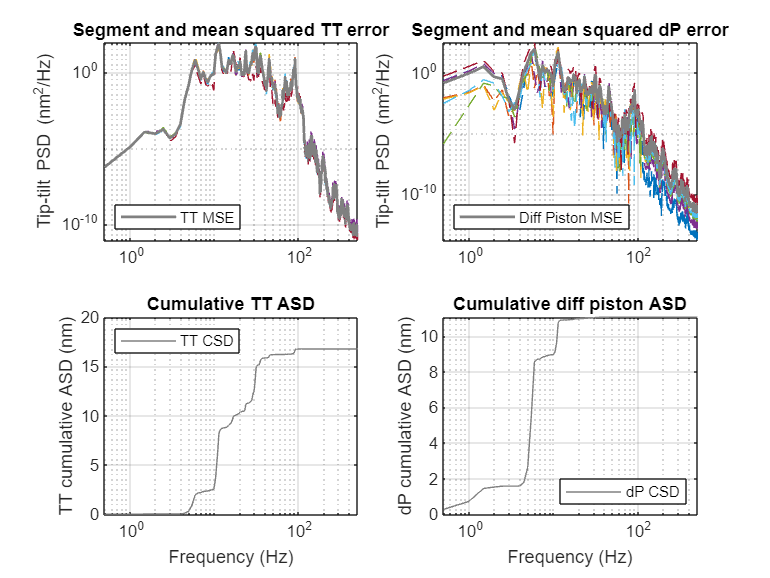

% TT PSD (nm^2/Hz)
bY_tt_nm2 = (10.2)^2 * (y_ttp_psd(1:7,:) + y_ttp_psd(8:14,:));
% Segment piston amplitude sprectral density - ASD (nm/sqrt(Hz))
bY_p_sqr = sqrt(y_ttp_psd(15:21,:));
% Differential piston PSD (nm^2/Hz)
bY_dp_nm2 = (abs(bY_p_sqr - 1.0*mean(bY_p_sqr))).^2;
% PSD plots
clf;
subplot(221);
loglog(om(2:end)/2/pi, bY_tt_nm2(:,2:end),'--'); hold on;
h_ = loglog(om(2:end)/2/pi, 1/7 *sum(bY_tt_nm2(:,2:end), 1)',...
    'color',[.5 .5 .5],'LineWidth',1.5); hold off;
grid on;
legend(h_,'TT MSE','Location','southwest');
ylabel('Tip-tilt PSD (nm^2/Hz)');
title('Segment and mean squared TT error')
subplot(222);
loglog(om(2:end)/2/pi, squeeze(bY_dp_nm2(:,2:end)),'--'); hold on;
h_ = loglog(om(2:end)/2/pi, 1/7 *sum(bY_dp_nm2(:,2:end), 1)',...
    'color',[.5 .5 .5],'LineWidth',1.5); hold off;
grid on;
legend(h_,'Diff Piston MSE','Location','southwest');
ylabel('Tip-tilt PSD (nm^2/Hz)');
title('Segment and mean squared dP error')
% Cumulative amplitude spectral density (ASD)
DeltaFs = diff(om/2/pi);
tt_CSD_nm = sqrt(1/7 *cumsum(DeltaFs .* sum(bY_tt_nm2(:,2:end), 1)'));
dp_CSD_nm = sqrt(1/7 *cumsum(DeltaFs .* sum(bY_dp_nm2(:,2:end), 1)'));
% Cumulative ASD plots
subplot(223);
semilogx(om(2:end)/2/pi, squeeze(tt_CSD_nm),'color',[.5 .5 .5]);
grid on;
legend('TT CSD','Location','northwest');
ylabel('TT cumulative ASD (nm)');
xlabel('Frequency (Hz)')
title('Cumulative TT ASD');

subplot(224);
semilogx(om(2:end)/2/pi, squeeze(dp_CSD_nm),'color',[.5 .5 .5]);
grid on;
legend('dP CSD','Location','southeast');
ylabel('dP cumulative ASD (nm)');
xlabel('Frequency (Hz)')
title('Cumulative diff piston ASD');

### Wavefront error (WFE) response to white-noise

One can approximate the wavefront error power spectral density induced by AHU vibration loads by combining the tip-tilt and differential piston contributions as

$Y_\text{wf}(j\omega) =

\frac{1}{7}
\sum_{i=1}^7
 \left(\rho^2 \breve{Y}_{\text{tt},i}(j\omega)
 +
\breve{Y}_{\text{dp},i}(j\omega)\right)
},$,

where $\rho = 10.2 \text{nm}/\text{mas}$ is a scaling factor. Below, we present the white-noise response $\left|Y_\text{wf}(j\omega)\right|$. That can be seen as the transfer function from the forces (and moments) applied in the M1 AHU nodes to the wavefront error.

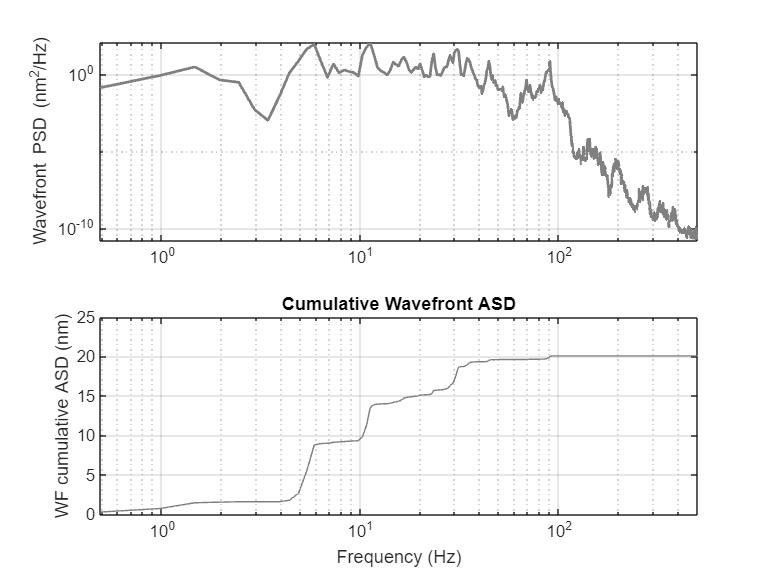

% WFE ASD
y_wf = (1/7) *(sum(bY_tt_nm2) + sum(bY_dp_nm2))';
wf_CSD_nm = sqrt(cumsum(DeltaFs .* y_wf(2:end)));
clf;
subplot(2,1,1)
loglog(om(2:end)/2/pi, y_wf(2:end),'color',[.5 .5 .5],'LineWidth',1.5);
grid on; xlim([om(2),om(end)]/2/pi);
ylabel('Wavefront PSD (nm^2/Hz)');
subplot(2,1,2)
semilogx(om(2:end)/2/pi, squeeze(wf_CSD_nm),'color',[.5 .5 .5]);
grid on; xlim([om(2),om(end)]/2/pi);
ylabel('WF cumulative ASD (nm)');
xlabel('Frequency (Hz)')
title('Cumulative Wavefront ASD');

### Overall wavefron error

Define the overall tip-tilt error contribution as


$$\epsilon_\text{tt} = 
\sqrt{\frac{1}{7}\int_0^{\infty} \sum_{i=1}^{7} \breve{Y}_{\text{tt},i}(j\omega) d\omega }$$


and the overall differential piston error contribution as


$$\epsilon_\text{dp} = \sqrt{\frac{1}{7}\int_0^{\infty} \sum_{i=1}^{7} \breve{Y}_{\text{dp},i}(j\omega) d\omega }.$$


Thus, the overall M1 AHU vibration effect on the wavefront error (WFE) is approximated with

$\epsilon_\text{WF} = \sqrt{\epsilon_\text{tt}^2 + \epsilon_\text{dp}^2}$.

total_tt = sqrt( (1/7)*sum(DeltaFs .* sum(bY_tt_nm2(:,2:end))'));
total_dp = sqrt( (1/7)*sum(DeltaFs .* sum(bY_dp_nm2(:,2:end))'));
% Check values WFE value: wf_CSD_nm = sqrt(sum(DeltaFs .* y_wf(2:end)))
total_wfe = sqrt(total_tt^2 + total_dp^2);
fprintf("Overall optical metrics (%s WFC mode):\nTT=%.3gnm \t Piston=%.3gnm \t WFE=%.3gnm \n",...
    WFC_MODE, total_tt, total_dp, total_wfe);

Overall optical metrics (LTAO WFC mode):
TT=16.8nm 	 Piston=11.1nm 	 WFE=20.1nm 
